clc;
clear ;
close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/20 , tfinal ,T_s)+gensig('sine' , tfinal/50 , tfinal ,T_s)+gensig('square' , tfinal/10 , tfinal ,T_s);
Noise2=-0.2+(0.2+0.2)*rand(numel(t),1);
u=u+Noise2;
y = lsim(sysd  ,u ,t);
for i=1:numel(t)
    paras(:,i)=[d(2:end),c]';
end
uu=300;


### sudden parameter resetting

for temp=uu:numel(y)
    if floor(temp/100)==temp/100
        cc= c(2:end)+c(2:end)*(rand);
        dd=d(2:end)+d(2:end)*(rand);
        paras(:,temp)=[dd,0,cc]';
    end
    
    y(temp)=[-(y(temp-1:-1:temp-4))',(u(temp-1:-1:temp-4))']*[dd,cc]';
end
    sys_dis = tf(dd ,[1 -cc], T_s)

sys_dis =
 
           -3.842 z^3 + 5.056 z^2 - 2.977 z + 0.6614
  -----------------------------------------------------------
  z^4 - 0.0004369 z^3 - 0.001204 z^2 + 0.001028 z + 0.0003165
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



    ident_change = d2c(sys_dis)

ident_change =
 
  -4106 s^3 - 9.739e04 s^2 - 7.699e05 s - 1.843e05
  -------------------------------------------------
  s^4 + 62.4 s^3 + 1865 s^2 + 2.744e04 s + 1.672e05
 
Continuous-time transfer function.



### smooth parameter variation 

% for temp=uu:numel(y)
%     paras(:,temp)=[d(2:end)+d(2:end)*.005*(sin((temp-uu)/2)),(c+c*.5*(sin((temp-uu)/2)-1))]';
%     y(temp)=[-(y(temp-1:-1:temp-4))',(u(temp:-1:temp-4))']*paras(:,temp);
% end
%     sys_dis = tf(c+c*.01*(sin(.01*(temp-uu))-1)' ,[1 -d(2:end)+d(2:end)*.001*(sin(.01*(temp-uu)))'], T_s)
%     ident_change = d2c(sys_dis)

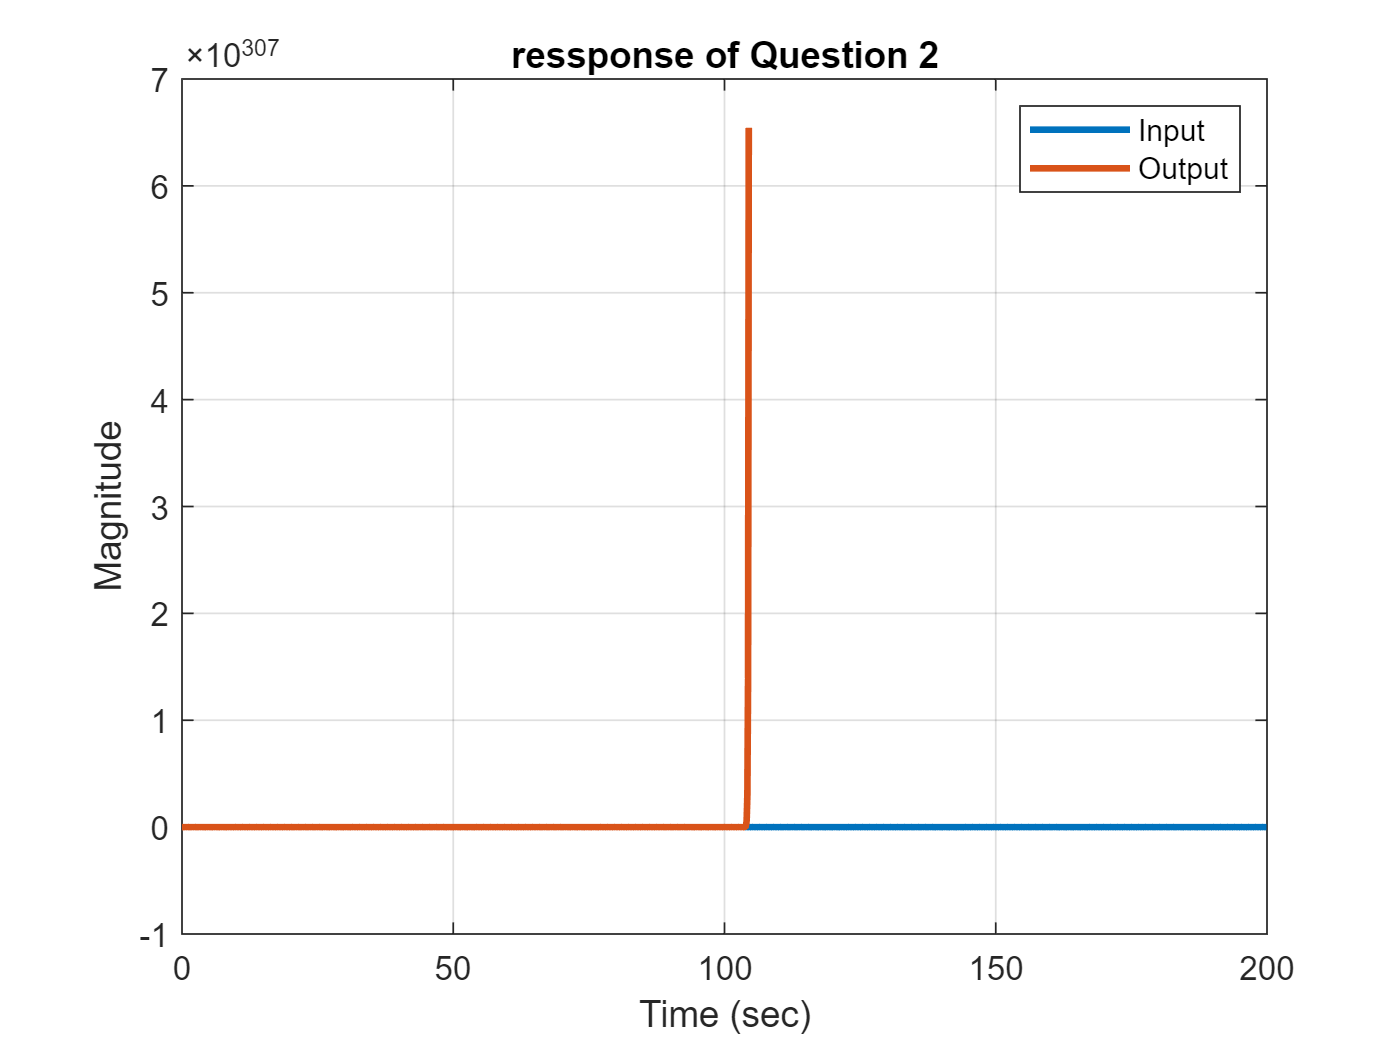

plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Magnitude') ;
title('ressponse of Question 2') ;
grid on
legend('Input','Output') ;

## Lanmbda-Recursive Least Square estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den

Nv = 8

% Nv = 10 ;
theta(:,1:Nv) = zeros(Nv , Nv) ;
P = 1e12*eye(Nv) ;
phi=[];
Eror=zeros(1,N);
norm=zeros(N,1);
y_hat(1:N,1)=zeros(N,1);
Step=-0.1:0.002:0

Step =    -0.1000   -0.0980   -0.0960   -0.0940   -0.0920   -0.0900   -0.0880   -0.0860   -0.0840   -0.0820   -0.0800   -0.0780   -0.0760   -0.0740   -0.0720   -0.0700   -0.0680   -0.0660   -0.0640   -0.0620   -0.0600   -0.0580   -0.0560   -0.0540   -0.0520   -0.0500   -0.0480   -0.0460   -0.0440   -0.0420   -0.0400   -0.0380   -0.0360   -0.0340   -0.0320   -0.0300   -0.0280   -0.0260   -0.0240   -0.0220   -0.0200   -0.0180   -0.0160   -0.0140   -0.0120   -0.0100   -0.0080   -0.0060   -0.0040   -0.0020


lambda=exp(Step)

lambda =     0.9048    0.9066    0.9085    0.9103    0.9121    0.9139    0.9158    0.9176    0.9194    0.9213    0.9231    0.9250    0.9268    0.9287    0.9305    0.9324    0.9343    0.9361    0.9380    0.9399    0.9418    0.9436    0.9455    0.9474    0.9493    0.9512    0.9531    0.9550    0.9570    0.9589    0.9608    0.9627    0.9646    0.9666    0.9685    0.9704    0.9724    0.9743    0.9763    0.9782    0.9802    0.9822    0.9841    0.9861    0.9881    0.9900    0.9920    0.9940    0.9960    0.9980


for i = (max(Parameters_in_num,Parameters_in_den)+1):N
    phi(:,i) = [(y(i-1:-1:i-Parameters_in_den))' , (u(i-1:-1:i-Parameters_in_num))']';
    K = P*phi(:,i)*((lambda(mod(i,numel(Step)-1)+1))+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P/lambda(mod(i,numel(Step)-1)+1) ;
    y_hat(i)=phi(:,i)'*theta(:,i-1);
    theta(:,i) = theta(:,i-1) + K*(y(i)-y_hat(i)); 
    norm(i)=(norm(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2)/2;
    Eror(i)=(Eror(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2);
end

RLS Convergence

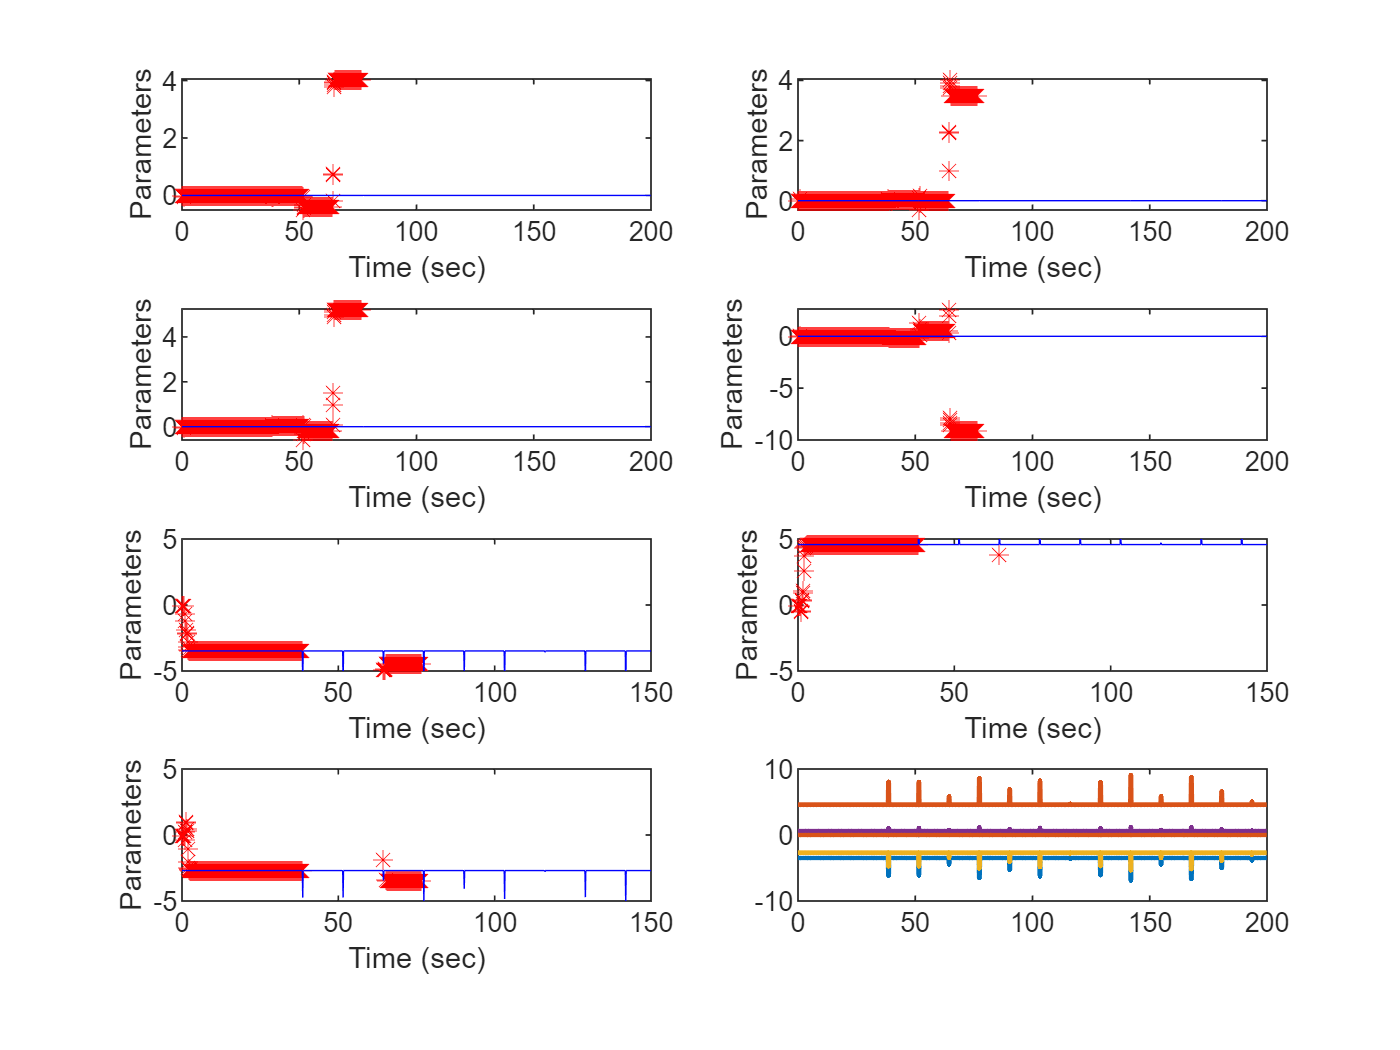

plot(t ,paras(:,:) , 'LineWidth' , 1.5)

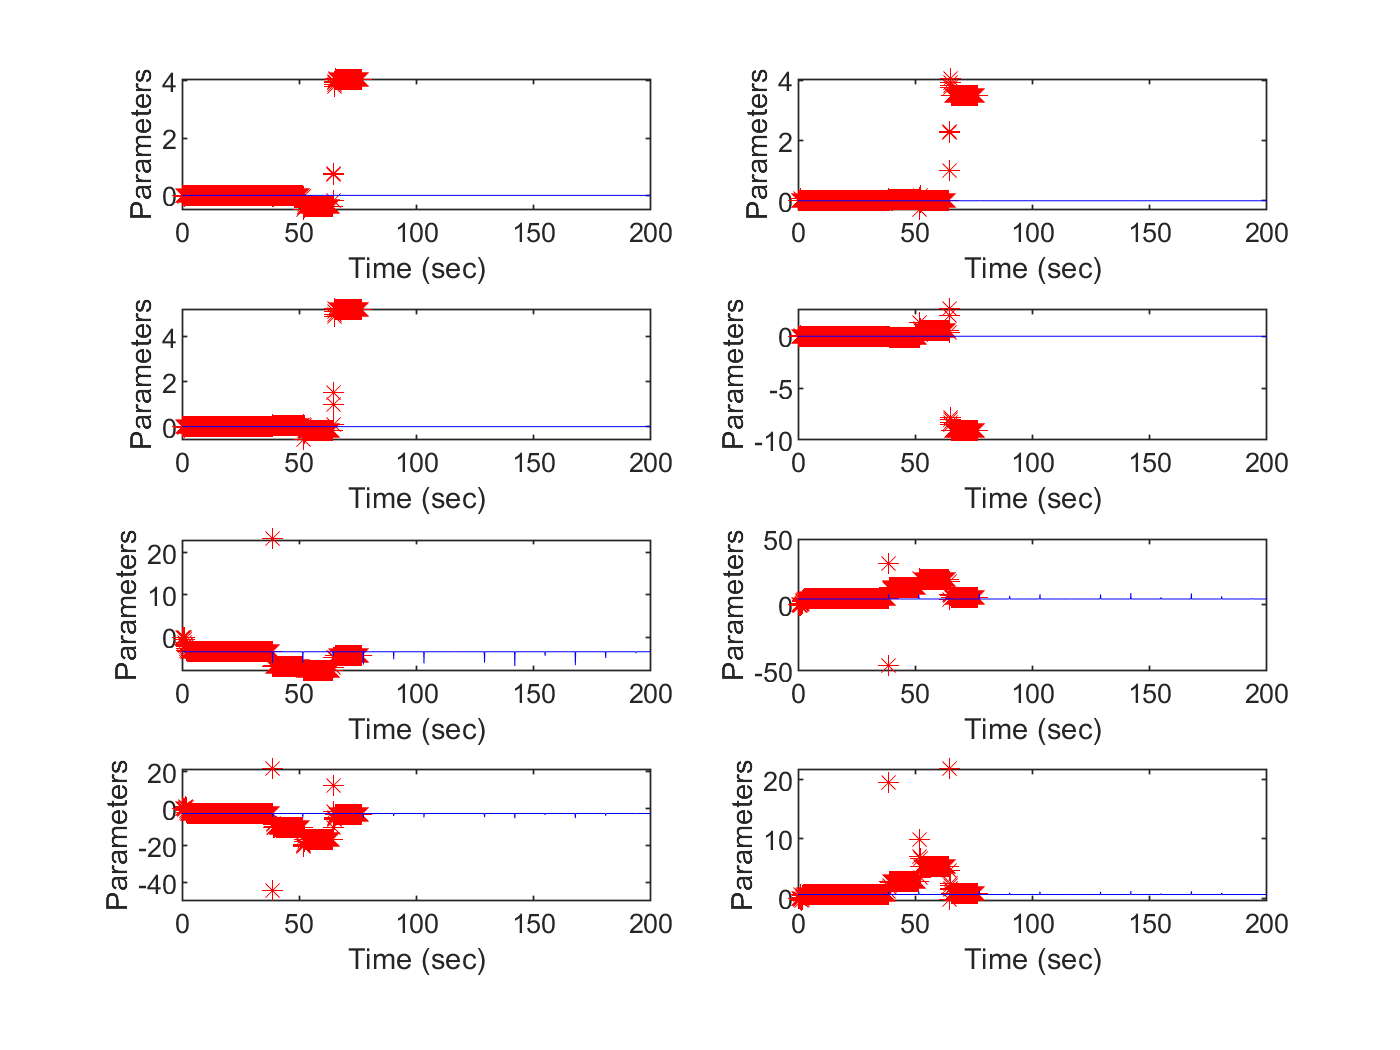

figure
grid on
for i=1:4
    subplot(4,2,i)
    plot(t , theta(4+i,:),'r*' ,t , paras(5+i,:) ,'b','LineWidth' , 0.25) ;
    xlabel('Time (sec)') ;
    ylabel('Parameters') ;
%     xlim([0 150])
%     ylim([-0.01  0.03])
end
for i=1:4
    subplot(4,2,4+i)
    plot(t , -theta(i,:) ,'r*',t , paras(i,:) ,'b', 'LineWidth' , 0.25) ;
    xlabel('Time (sec)') ;
    ylabel('Parameters') ;
%      xlim([0 150])
%      ylim([-5  5])
end

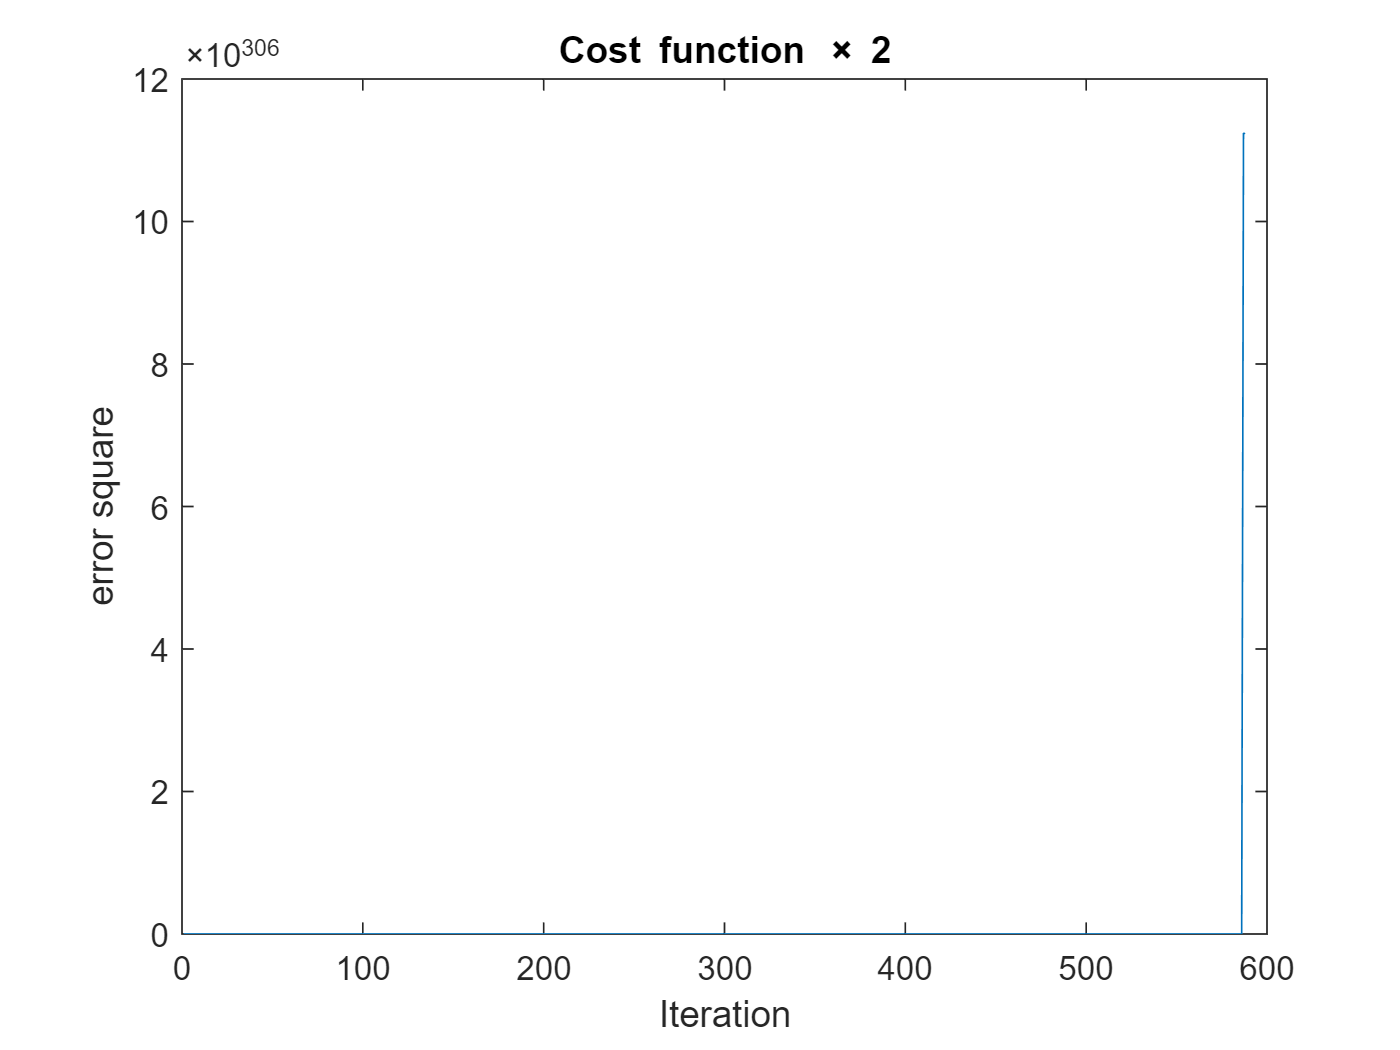

figure
plot(1:1:N,Eror)
xlabel('Iteration') ;
ylabel('error square') ;
title('Cost function \times 2') ;

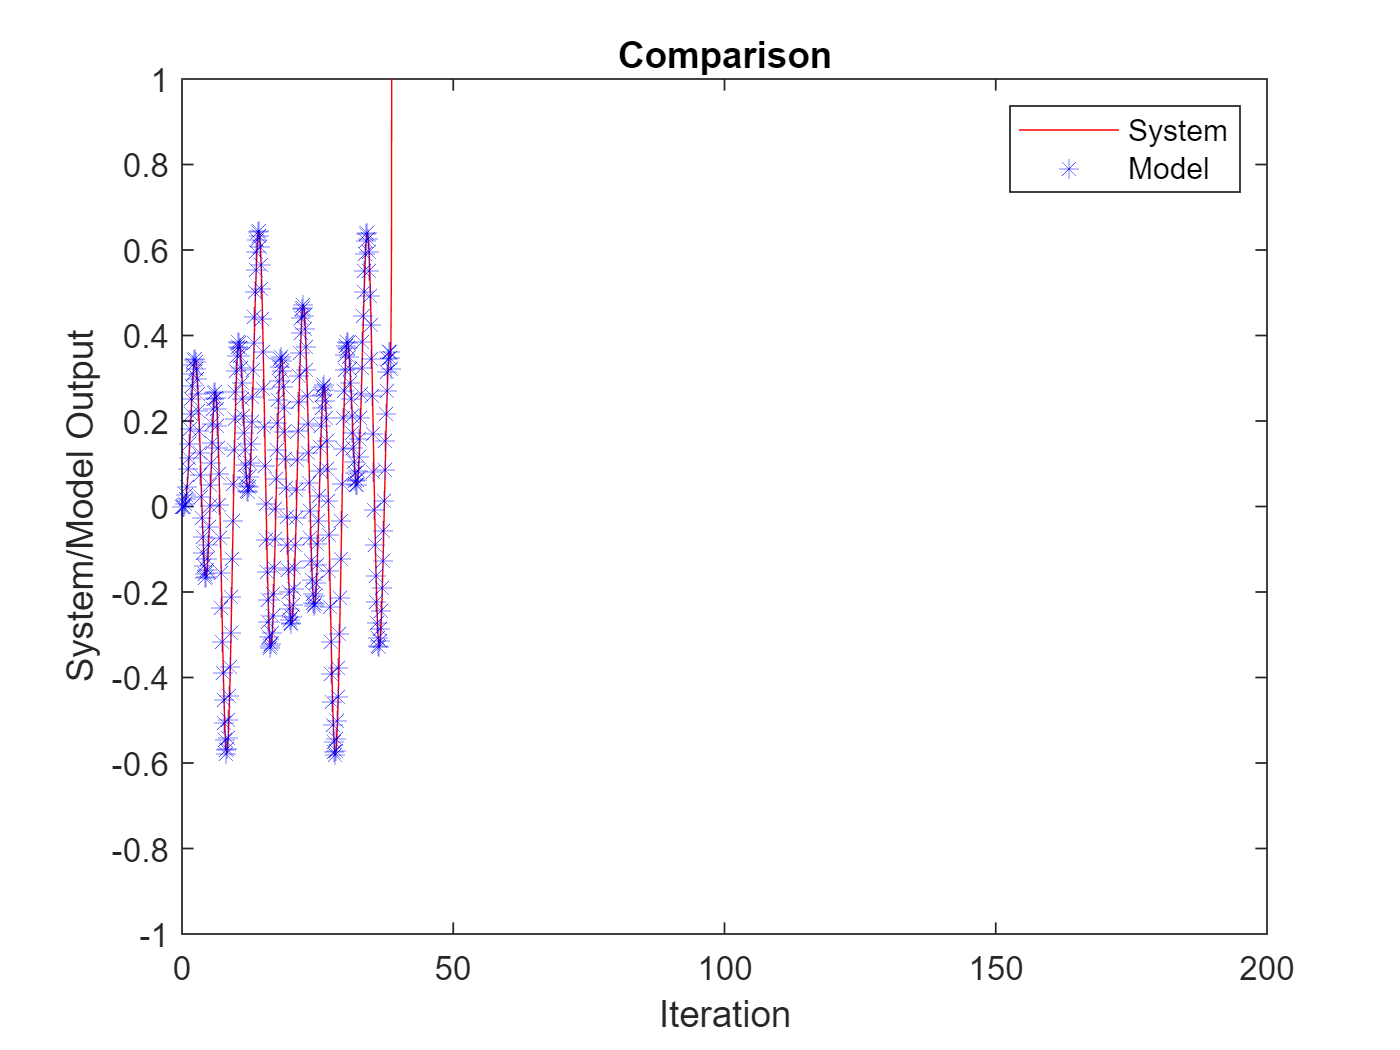

plot(t,y,'r',t,y_hat,'b*','LineWidth',0.15)
xlabel('Iteration') ;
ylabel('System/Model Output') ;
title('Comparison') ;
xlim([0 200])
ylim([-1 1])
legend('System','Model')